General Functions to clear command window, remove items from workspace and to close figures.

clc;
clear all;
close all;

A sampling frequency of 120 kHz and a cut-off frequency of 54 kHz are chosen as input parameters for the second order filter

fs = 120000;
t=1/fs;

Specifications for the analog Butterworth filter

filterOrder =2;  % Second-order filter
cutoffFreq = 54000;  % Cut-off frequency in Hz

'butter' command is used to design the Butterworth filter in analog domain and frequency response is computed.

Design the Butterworth filter in the analog domain

[b, a] = butter (filterOrder, 2*pi*cutoffFreq, 's');  % 's' for continuous-time filter design

% Compute the frequency response of the analog filter

[H, w] = freqs (b, a, logspace(1, 6, 1000));  % Frequency response in log scale

'butter' command is used to design the Butterworth filter in analog domain and frequency response is computed.

Plot the magnitude response of the analog filter

figure;
subplot(2,1,1);
semilogx(w/(2*pi), 20*log10(abs(H)));  % Convert rad/s to Hz for x-axis
title ('Frequency Response of 2nd Order Butterworth Low-Pass Filter (Analog)');
xlabel ('Frequency (Hz)');
ylabel ('Magnitude (dB)');
grid on;

Plot the phase response of the analog filter

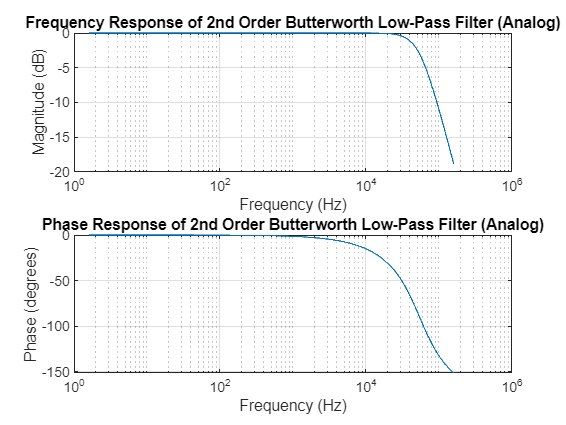

subplot (2,1,2);
semilogx(w/(2*pi), angle(H) * (180/pi));  % Convert rad/s to Hz for x-axis
title ('Phase Response of 2nd Order Butterworth Low-Pass Filter (Analog)');
xlabel ('Frequency (Hz)');
ylabel ('Phase (degrees)');
grid on;

Converting Analog filter to Digital filter and to get filter coeffecients from transfer function using Bilinear Transformation. 

'c2d' convert model from continuous time to discrete time. 'tustin' function can be used for bilinear discretization. 'tfdata' can be used to access transfer function data and to get the filter coeffecients

% Convert the analog filter to a transfer function
Hs = tf (b, a);
% Convert the analog filter to digital using c2d with bilinear transformation
Hd = c2d (Hs, t, 'tustin');
% Extract the digital filter coefficients
[b_d, a_d] = tfdata (Hd, 'v');
disp ('Coefficients of the digital filter (b, a):');

Coefficients of the digital filter (b, a):


Frequency response of the digital filter

w_d = 0:0.01: pi;
[h_d, om_d] = freqz (b_d, a_d, w_d);
m_d = 20*log10(abs(h_d));
an_d = angle(h_d);


Plotting the frequency response of the digital filter

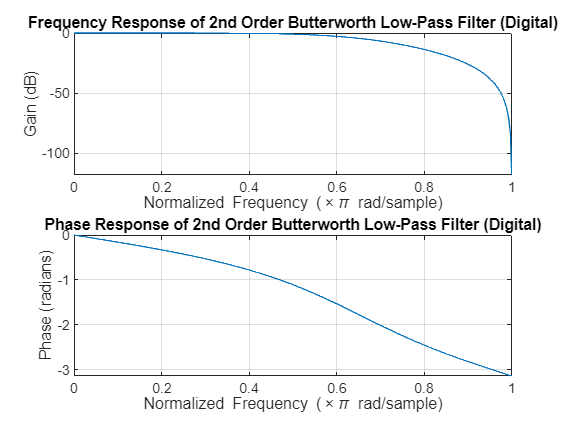

figure;
subplot (2,1,1);
plot (om_d/pi, m_d);
title ('Frequency Response of 2nd Order Butterworth Low-Pass Filter (Digital)');
xlabel ('Normalized Frequency (\times\pi rad/sample)');
ylabel ('Gain (dB)');
grid on;

subplot (2,1,2);
plot (om_d/pi, an_d);
title ('Phase Response of 2nd Order Butterworth Low-Pass Filter (Digital)');
xlabel ('Normalized Frequency (\times\pi rad/sample)');
ylabel ('Phase (radians)');
grid on;

Displaying the Direct Form II Equation

% Direct Form II equations
disp ('Direct Form II equations:');

Direct Form II equations:


Generating a sine wave with a frequency of 1000Hz to use it as an input signal.

Initializing the sequence parameters to zero and applying filter equations to get the output signal.

% Define time parameters
numSamples = 250;
time = (0:numSamples-1) * t;

% Generate the input signal x(n) as a sine wave
f = 1000;
x = sin(2*pi*f*time);

% Initialize signals
v = zeros (1, numSamples); % Initialize v(n)
y = zeros (1, numSamples); % Initialize y(n)

% Initialize initial conditions
v(1) = 0;
v(2) = 0;

% Compute v(n) and y(n) using Direct Form II equations
for n = 3:numSamples
    v(n) = x(n) - a_d(2) * v(n-1) - a_d(3) * v(n-2);
    y(n) = b_d(1) * v(n) + b_d(2) * v(n-1) + b_d(3) * v(n-2);
end

Plotting input signal, output signal and input vs output comparison graph

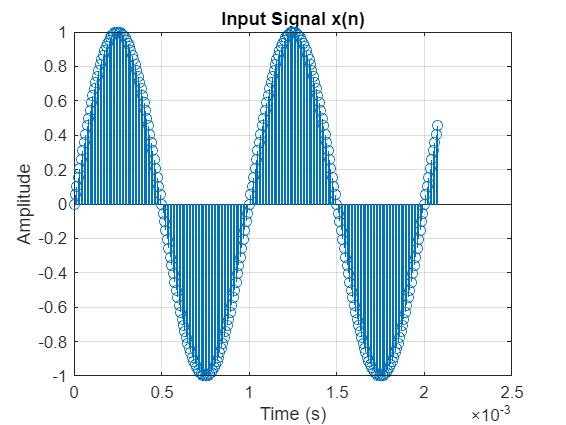

figure;
stem (time, x);
title ('Input Signal x(n)');
xlabel ('Time (s)');
ylabel ('Amplitude');
grid on;

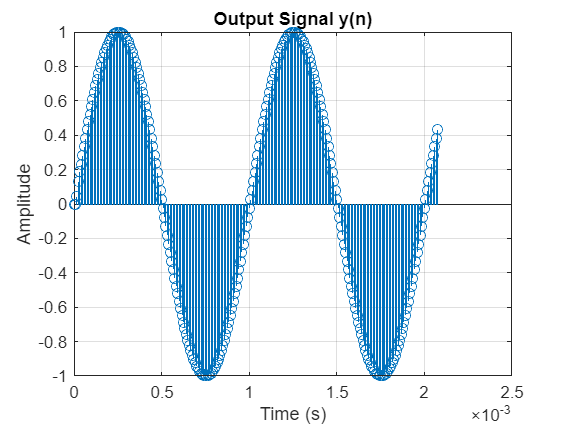


figure;
stem (time, y);
title ('Output Signal y(n)');
xlabel ('Time (s)');
ylabel('Amplitude');
grid on;

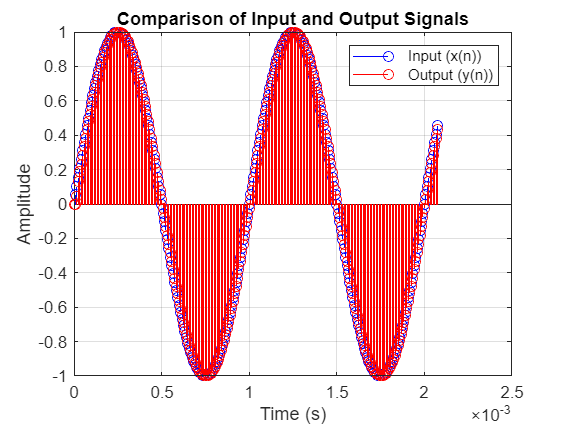


figure;
stem (time, x, 'b');
hold on;
stem (time, y, 'r');
title ('Comparison of Input and Output Signals');
xlabel ('Time (s)');
ylabel('Amplitude');
legend ('Input (x(n))', 'Output (y(n))');
grid on;